
=== Vibration Analysis (PID) ===
omega_n = 70.7107 rad/s | f_n = 11.2540 Hz | zeta = 0.7071
PID gains: Kp = 1000, Kd = 30, Ki = 0


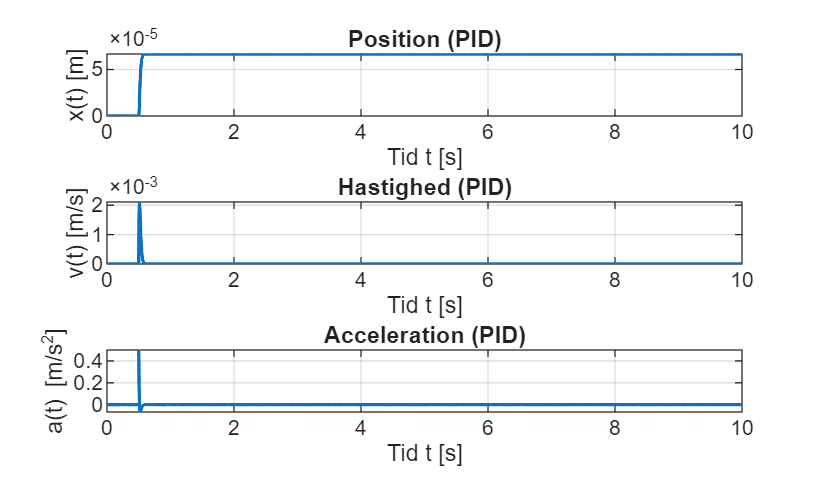

function out = vibration_analysis_system_PID(m, k, c, x0, v0, F_func, t_end, opts)
% VIBRATION_ANALYSIS_SYSTEM_PID
%   m*xdd + c*xd + k*x = F_dist(t) + F_ctrl(t)
%
% PID (x_ref = 0):
%   e  = -x
%   ed = -xd
%   ei = -∫x dt
%   F_ctrl = Kp*e + Kd*ed + Ki*ei = -Kp*x - Kd*xd - Ki*z
% where z = ∫x dt
%
% opts:
%   opts.Kp, opts.Kd, opts.Ki
%   opts.z0 (initial integral state, default 0)
%   opts.solver ("ode45" default)
%   opts.RelTol, opts.AbsTol
%   opts.doPlot, opts.verbose

%% Defaults
if nargin < 6 || isempty(F_func)
    F_func = @(t) zeros(size(t));
end
if nargin < 8 || isempty(opts)
    opts = struct();
end

if ~isfield(opts,"Kp") || isempty(opts.Kp), opts.Kp = 0; end
if ~isfield(opts,"Kd") || isempty(opts.Kd), opts.Kd = 0; end
if ~isfield(opts,"Ki") || isempty(opts.Ki), opts.Ki = 0; end
if ~isfield(opts,"z0") || isempty(opts.z0), opts.z0 = 0; end

if ~isfield(opts,"solver")  || isempty(opts.solver),  opts.solver  = "ode45"; end
if ~isfield(opts,"RelTol")  || isempty(opts.RelTol),  opts.RelTol  = 1e-8;    end
if ~isfield(opts,"AbsTol")  || isempty(opts.AbsTol),  opts.AbsTol  = 1e-10;   end
if ~isfield(opts,"doPlot")  || isempty(opts.doPlot),  opts.doPlot  = true;    end
if ~isfield(opts,"verbose") || isempty(opts.verbose), opts.verbose = true;    end

Kp = opts.Kp; Kd = opts.Kd; Ki = opts.Ki;
z0 = opts.z0;

out = struct();
out.params = struct('m',m,'k',k,'c',c,'x0',x0,'v0',v0,'Kp',Kp,'Kd',Kd,'Ki',Ki);

omega_n = sqrt(k/m);
zeta    = c/(2*sqrt(m*k));
f_n     = omega_n/(2*pi);
out.info = struct('omega_n',omega_n,'zeta',zeta,'f_n',f_n);

if opts.verbose
    fprintf('\n=== Vibration Analysis (PID) ===\n');
    fprintf('omega_n = %.4f rad/s | f_n = %.4f Hz | zeta = %.4f\n', omega_n, f_n, zeta);
    fprintf('PID gains: Kp = %.4g, Kd = %.4g, Ki = %.4g\n', Kp, Kd, Ki);
end

%% Auto sim time
if nargin < 7 || isempty(t_end)
    if zeta < 1
        omega_d = omega_n*sqrt(1 - zeta^2);
        T_d     = 2*pi/omega_d;
        t_end   = 10*T_d;
    else
        t_end = 10/(max(zeta,1e-6)*omega_n);
    end
end
tspan = [0 t_end];
out.info.t_end = t_end;

%% State: y = [x; v; z] where z = ∫x dt
y0 = [x0; v0; z0];

eom = @(t,y) [ ...
    y(2); ...
    (F_total(t,y) - c*y(2) - k*y(1))/m; ...
    y(1) ...  % z_dot = x
    ];

    function Ft = F_total(t,y)
        Fd = F_func(t);
        x  = y(1);
        v  = y(2);
        z  = y(3);

        % PID control (x_ref = 0)
        Fc = -Kp*x - Kd*v - Ki*z;

        Ft = Fd + Fc;
    end

%% Solve
odeOpts = odeset('RelTol', opts.RelTol, 'AbsTol', opts.AbsTol);
switch lower(string(opts.solver))
    case "ode45"
        [T, Y] = ode45(eom, tspan, y0, odeOpts);
    case "ode15s"
        [T, Y] = ode15s(eom, tspan, y0, odeOpts);
    otherwise
        error('Ukendt solver "%s". Brug "ode45" eller "ode15s".', string(opts.solver));
end

X = Y(:,1);
V = Y(:,2);
Z = Y(:,3);

Fdist = F_func(T);
Fctrl = -Kp*X - Kd*V - Ki*Z;
Ftot  = Fdist + Fctrl;

A = (Ftot - c*V - k*X)/m;

out.T = T; out.X = X; out.V = V; out.Z = Z;
out.Fdist = Fdist; out.Fctrl = Fctrl; out.Ftotal = Ftot;
out.A = A;

out.metrics.xPeak = peakMetric(T, X);
out.metrics.vPeak = peakMetric(T, V);
out.metrics.aPeak = peakMetric(T, A);

%% Plot
if opts.doPlot
    figure;

    subplot(3,1,1);
    plot(T, X, 'LineWidth', 1.3);
    grid on; xlabel('Tid t [s]'); ylabel('x(t) [m]'); title('Position (PID)');

    subplot(3,1,2);
    plot(T, V, 'LineWidth', 1.3);
    grid on; xlabel('Tid t [s]'); ylabel('v(t) [m/s]'); title('Hastighed (PID)');

    subplot(3,1,3);
    plot(T, A, 'LineWidth', 1.3);
    grid on; xlabel('Tid t [s]'); ylabel('a(t) [m/s^2]'); title('Acceleration (PID)');
end

end

function pm = peakMetric(T, S)
[mag, idx] = max(abs(S));
pm = struct('t', T(idx), 'mag', mag, 'value', S(idx));
end

% Scenarie 1 "Konstant forstyrrelse"

m=0.4; k=2000; c=40;
x0=0; v0=0;

F_bias = 0.2;
F_func = @(t) (t>=0.5).*F_bias;   % step ved 0.5 s
t_end = 10;

opts.Ki = 0;
outKi0 = vibration_analysis_system_PID(m,k,c,0,0,F_func,t_end,opts);


=== Vibration Analysis (PID) ===
omega_n = 70.7107 rad/s | f_n = 11.2540 Hz | zeta = 0.7071
PID gains: Kp = 1000, Kd = 30, Ki = 200


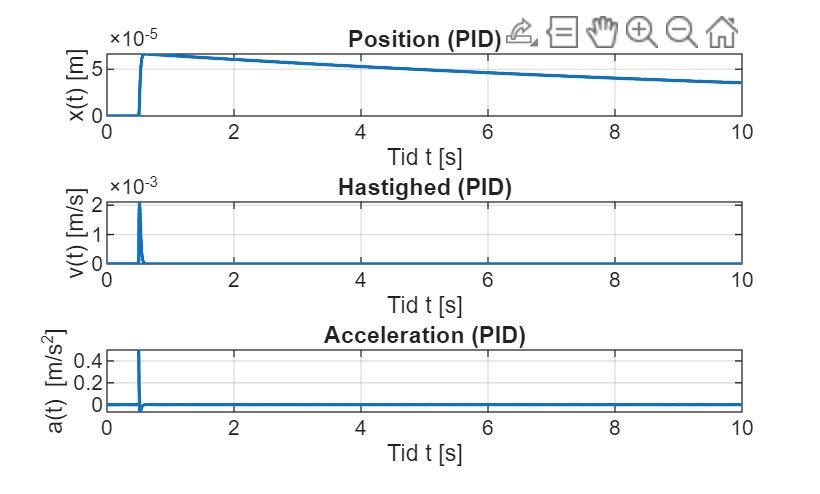


opts.Ki = 200;
outKi200 = vibration_analysis_system_PID(m,k,c,0,0,F_func,t_end,opts);